% data_path = "C:\Users\wynga\OneDrive\Desktop\PhD_Research\Misc\NFL Gambling\NFL 2023 to 2024 Season Money Lines.xlsx";
% 
% warning off
% for week_number = 5:18
%     % Action Network Data only Available after Week 4
%     data_table = readtable(data_path,'Sheet',sprintf('Week %d',week_number));
%     num_games = length(data_table.Teams)/2;
%     for game_number = 1:num_games
%         game_data(week_number,game_number).home_team = data_table.Teams{2*game_number};
%         game_data(week_number,game_number).home_outcome = data_table.Outcome{2*game_number};
%         game_data(week_number,game_number).home_opening_odds = data_table.OpeningMoneyline(2*game_number);
%         game_data(week_number,game_number).home_best_odds = data_table.BestOdds(2*game_number);
%         game_data(week_number,game_number).home_power_ranking = data_table.PowerRanking(2*game_number);
%         game_data(week_number,game_number).home_bet_percent = data_table.x_OfBets(2*game_number);
%         game_data(week_number,game_number).home_money_percent = data_table.x_OfMoney(2*game_number);
% 
%         game_data(week_number,game_number).away_team = data_table.Teams{2*game_number-1};
%         game_data(week_number,game_number).away_outcome = data_table.Outcome{2*game_number-1};
%         game_data(week_number,game_number).away_opening_odds = data_table.OpeningMoneyline(2*game_number-1);
%         game_data(week_number,game_number).away_best_odds = data_table.BestOdds(2*game_number-1);
%         game_data(week_number,game_number).away_power_ranking = data_table.PowerRanking(2*game_number-1);
%         game_data(week_number,game_number).away_bet_percent = data_table.x_OfBets(2*game_number-1);
%         game_data(week_number,game_number).away_money_percent = data_table.x_OfMoney(2*game_number-1);
%     end
% 
%     for game_number = num_games+1:16
%         % For Teams on a Bye Week
%         game_data(week_number,game_number).home_team = 'NA';
%         game_data(week_number,game_number).home_outcome = 'NA';
%         game_data(week_number,game_number).home_opening_odds = nan;
%         game_data(week_number,game_number).home_best_odds = nan;
%         game_data(week_number,game_number).home_power_ranking = nan;
%         game_data(week_number,game_number).home_bet_percent = nan;
%         game_data(week_number,game_number).home_money_percent= nan;
% 
%         game_data(week_number,game_number).away_team = 'NA';
%         game_data(week_number,game_number).away_outcome = 'NA';
%         game_data(week_number,game_number).away_opening_odds = nan;
%         game_data(week_number,game_number).away_best_odds = nan;
%         game_data(week_number,game_number).away_power_ranking = nan;
%         game_data(week_number,game_number).away_bet_percent = nan;
%         game_data(week_number,game_number).away_money_percent = nan;
%     end
% 
% end
% 
% for week_number = 1:4
%     % For Weeks without Action Network Data
%     for game_number = 1:16
% 
%         game_data(week_number,game_number).home_team = 'NA';
%         game_data(week_number,game_number).home_outcome = 'NA';
%         game_data(week_number,game_number).home_opening_odds = nan;
%         game_data(week_number,game_number).home_best_odds = nan;
%         game_data(week_number,game_number).home_power_ranking = nan;
%         game_data(week_number,game_number).home_bet_percent = nan;
%         game_data(week_number,game_number).home_money_percent= nan;
% 
%         game_data(week_number,game_number).away_team = 'NA';
%         game_data(week_number,game_number).away_outcome = 'NA';
%         game_data(week_number,game_number).away_opening_odds = nan;
%         game_data(week_number,game_number).away_best_odds = nan;
%         game_data(week_number,game_number).away_power_ranking = nan;
%         game_data(week_number,game_number).away_bet_percent = nan;
%         game_data(week_number,game_number).away_money_percent = nan;
%     end
% end
% 
% warning on
% 
% team_names = sort(horzcat({game_data(18,:).home_team},{game_data(18,:).away_team}));
% % 'ARI' 'ATL' 'BAL' 'BUF' 'CAR' 'CHI' CIN' 'CLE' 'DAL' 'DEN' 'DET' 'GB'
% % 'HOU' 'IND' 'JAX' 'KC' 'LAC' 'LAR' 'LV' 'MIA' 'MIN' 'NE' 'NO' 'NYG'
% % 'NYJ' 'PHI' 'PIT' 'SEA' 'SF' 'TB' 'TEN' 'WAS'

## Reverse Engineering

% % Let's Monte Carlo this shit!
% mu_mesh = .375:.001:.625;
% sigma_mesh = .01:.001:.15;
% 
% relevant_games = {};
% % Cell Array of [week_number,game_number] for games with provided opening
% % odds and (palpha+pbeta)/2 that fall within the mu_mesh
% 
% for week_number = 1:18
%     for game_number = 1:16
%         alpha = min(game_data(week_number,game_number).home_opening_odds,game_data(week_number,game_number).away_opening_odds);
%         beta = max(game_data(week_number,game_number).home_opening_odds,game_data(week_number,game_number).away_opening_odds);
% 
%         if isnan(alpha) || isnan(beta)
%             continue
%         end
% 
%         palpha = -alpha/(100-alpha);
%         pbeta = beta/(100+beta);
% 
%         if ((palpha+pbeta)/2 < mu_mesh(1)) || ((palpha+pbeta)/2 > mu_mesh(end))
%             continue
%         end
% 
%         relevant_games{length(relevant_games)+1} = [week_number,game_number];
%     end
% end
% 
% num_relevant_games = length(relevant_games);
% total_games = 16*18;
% 
% mu_array = nan(1,num_relevant_games);
% sigma_array = nan(1,num_relevant_games);
% checks_out_array = nan(1,num_relevant_games);
% 
% f = waitbar(0,'Starting Process','Name','Solving For Money Density Parameters');
% for index = 1:num_relevant_games
% 
%     waitbar(index/num_relevant_games,f,sprintf('%.1f Percent Complete',100*index/num_relevant_games));
% 
%     game_array = relevant_games{index};
%     week_number = game_array(1);
%     game_number = game_array(2);
% 
%     alpha = min(game_data(week_number,game_number).home_opening_odds,game_data(week_number,game_number).away_opening_odds);
%     beta = max(game_data(week_number,game_number).home_opening_odds,game_data(week_number,game_number).away_opening_odds);
% 
%     palpha = -alpha/(100-alpha);
%     pbeta = beta/(100+beta);
% 
%     my_pdf = @(p,mu,sigma) modified_beta(p,mu,sigma);
%     my_cdf = @(p,mu,sigma) modified_beta_cdf(p,mu,sigma);
%     tolerance = 20; % In terms of Basis Points
% 
%     p_c = @(mu,sigma) Reverse_Engineer.prime_constraint(my_pdf,my_cdf,pbeta,palpha,mu,sigma);
%     d_c = @(mu,sigma) Reverse_Engineer.derived_constraint(my_pdf,my_cdf,pbeta,palpha,mu,sigma);
% 
%     lowest_constraint = inf;
%     mu_chosen = nan;
%     sigma_chosen = nan;
%     for mu_tested = mu_mesh
%         for sigma_tested = sigma_mesh
%             constraint_value = max(abs(p_c(mu_tested,sigma_tested)),abs(d_c(mu_tested,sigma_tested)));
%             if constraint_value < lowest_constraint
%                 lowest_constraint = constraint_value;
%                 mu_chosen = mu_tested;
%                 sigma_chosen = sigma_tested;
%             end
%         end
%     end
% 
%     % Checking By Solving Back for palpha and pbeta with chosen parameters
% 
%     chosen_pdf = @(p,mu,sigma) modified_beta(p,mu_chosen,sigma_chosen);
%     chosen_cdf = @(p,mu,sigma) modified_beta_cdf(p,mu_chosen,sigma_chosen);
% 
%     s_u = @(pbeta,palpha) Gambling.system_utility(chosen_pdf,chosen_cdf,pbeta,palpha);
%     p_c = @(pbeta,palpha) Gambling.prime_constraint(chosen_pdf,chosen_cdf,pbeta,palpha);
% 
%     % Numerical Solution
%     [moneyline_struct.pbeta_numerical,moneyline_struct.palpha_numerical,moneyline_struct.profit_numerical] = ...
%         Numerical.solver(s_u,p_c,[.375 .625],tolerance/10000,"grainSize",.001);
% 
%     alpha_numerical = 100*moneyline_struct.palpha_numerical/(1-moneyline_struct.palpha_numerical);
%     beta_numerical = 100*moneyline_struct.pbeta_numerical/(1-moneyline_struct.pbeta_numerical);
% 
%     alpha_checks_out = abs(-alpha-alpha_numerical) <= 2;
%     beta_checks_out = abs(beta-beta_numerical) <= 2;
% 
%     checks_out_array(index) = alpha_checks_out && beta_checks_out;
%     if ~checks_out_array(index) 
%         if ~alpha_checks_out
%             fprintf('Expected Alpha: %g, Actual Alpha: %g\n',-alpha,alpha_numerical)
%         end
%         if ~beta_checks_out
%             fprintf('Expected Beta: %g, Actual Beta: %g\n',beta,beta_numerical)
%         end
%     end
% 
%     mu_array(index) = mu_chosen;
%     sigma_array(index) = sigma_chosen;
% end
% close(f)
% 
% data_path = 'C:\Users\wynga\OneDrive\Desktop\PhD_Research\Data\Sigma and Mu for 2023 NFL Moneylines';
% save(horzcat(data_path,'\','mu_array.mat'),"mu_array")
% save(horzcat(data_path,'\','sigma_array.mat'),"sigma_array")
% save(horzcat(data_path,'\','checks_out_array.mat'),"checks_out_array")

## Histograms and Such

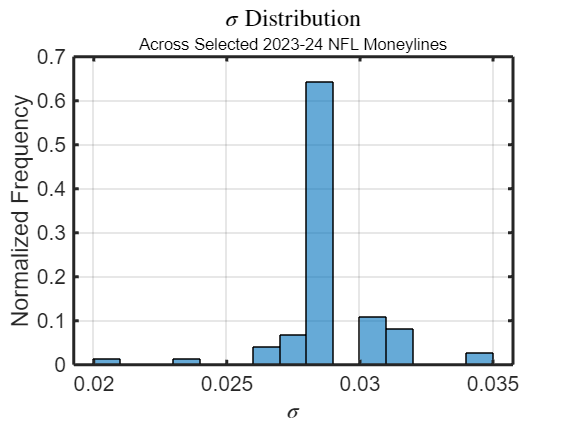

data_path = 'C:\Users\wynga\OneDrive\Desktop\PhD_Research\Data\Sigma and Mu for 2023 NFL Moneylines';
load(horzcat(data_path,'\','mu_array.mat'),"mu_array")
load(horzcat(data_path,'\','sigma_array.mat'),"sigma_array")
load(horzcat(data_path,'\','checks_out_array.mat'),"checks_out_array")

histogram(sigma_array(logical(checks_out_array)),'BinWidth',.001,'Normalization','probability')
xlabel('$\sigma$','Interpreter','latex')
ylabel('Normalized Frequency')
title('$\sigma$ Distribution','Interpreter','latex')
subtitle('Across Selected 2023-24 NFL Moneylines')
sexy_plot


num_games_used = sum(checks_out_array)

num_games_used = 73

## Profitability with Mu = .5, Sigma = .035

mu = .5;
sigma = .03;

my_pdf = @(p) modified_beta(p,mu,sigma);
my_cdf = @(p) modified_beta_cdf(p,mu,sigma);
tolerance = 5; % In terms of Basis Points

moneyline_struct = moneyline_solver(my_pdf,my_cdf,tolerance)

effective_profitability = 0.0421

moneyline_struct = struct with fields:
     pbeta_numerical: 0.4780
    palpha_numerical: 0.5220
    profit_numerical: 0.0197
        pbeta_newton: NaN
       palpha_newton: NaN
       profit_newton: NaN
     matched_answers: 0



money_bet = 1-(my_cdf(moneyline_struct.palpha_numerical)-my_cdf(moneyline_struct.pbeta_numerical))

money_bet = 0.4675

relative_profit = moneyline_struct.profit_numerical/money_bet

relative_profit = 0.0421